## ARCHIVO EJEMPLO DE MUESTREO DE DATASET 

En este script se muestra el procedimiento para conseguir la división del dataset en los grupos de entrenamiento y test. Para ello se va a utilizar la base de datos Iris, es una de las base de datos más conocida que se encuentran en la literatura de reconocimiento de patrones. 

Esta base de datos, recolectada durante varios años por Edgar Anderson fue utilizada para demostrar que estas medidas podrían utilizarse para diferenciar entre especies de plantas iris. Contiene 3 clases de 50 casos cada una, donde cada clase se refiere a un tipo de planta iris.

Una clase es linealmente separable de los otras 2; estas últimas no son linealmente separables entre sí.

Los atributos son:

- Longitud del sépalo en cm (Sepal.Length)

- Ancho del sépalo en cm (Sepal.Width)

- Longitud del pépalo en cm (Petal.Length)

- Ancho del pépalo en cm (Pepal.Width)

- Clase (Species):

- Iris Setosa

- Iris Versicolour

- Iris Virginica

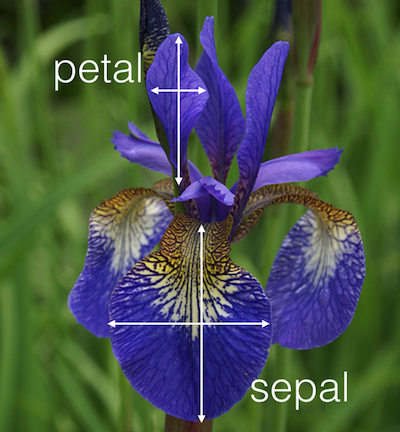

clear all
close all
clc

load iris.dat
No_examples=length(iris)

No_examples = 150

Se establece aleatoriamente a partir de la semilla el orden de los 150 datos. Con esto se mezcla el dataset para obtener fácilmente una muestra aleatorio del mismo que contenga todas las clases.

rng(2021)
ind=randperm(No_examples);

## **DIVISIÓN DE LOS DATOS DE ENTRENAMIENTO Y TEST (60-40)**

Inicialmente se calulan el número de muestras de entrenamiento y test.

No_examples_train60=0.6*No_examples

No_examples_train60 = 90

No_examples_test40=0.4*No_examples

**Creación del Dataset de entrenamiento (60% del Dataset total)**

iris_train60=iris(ind(1:No_examples_train60),:)

**Creación del Dataset de Test  (40% del Dataset total)**

iris_test40=iris(ind(No_examples_train60+1:end),1:4)

iris_train60 =     48    34    16     2     1
    59    32    48    18     2
    50    20    35    10     2
    72    32    60    18     3
    47    32    16     2     1
    69    31    54    21     3
    69    31    51    23     3
    58    40    12     2     1
    56    30    45    15     2
    54    37    15     2     1


iris_testclass40=iris(ind(No_examples_train60+1:end),5)

## **DIVISIÓN DE LOS DATOS DE ENTRENAMIENTO Y TEST (70-30)**

Inicialmente se calulan el número de muestras de entrenamiento y test.

No_examples_train70=0.7*No_examples

iris_test40 =     63    27    49    18
    64    31    55    18
    44    29    14     2
    48    31    16     2
    61    30    49    18
    62    34    54    23
    68    28    48    14
    58    27    39    12
    67    31    56    24
    77    38    67    22


No_examples_test30=0.3*No_examples

iris_testclass40 =      3
     3
     1
     1
     3
     3
     2
     2
     3
     3


**Creación del Dataset de entrenamiento (70% del Dataset total)**

iris_train70=iris(ind(1:No_examples_train70),:)

**Creación del Dataset de Test  (30% del Dataset total)**

iris_test30=iris(ind(No_examples_train70+1:end),:)

iris_train70 =     48    34    16     2     1
    59    32    48    18     2
    50    20    35    10     2
    72    32    60    18     3
    47    32    16     2     1
    69    31    54    21     3
    69    31    51    23     3
    58    40    12     2     1
    56    30    45    15     2
    54    37    15     2     1


## **DIVISIÓN DE LOS DATOS DE ENTRENAMIENTO Y TEST (80-20)**

Inicialmente se calulan el número de muestras de entrenamiento y test.

No_examples_train80=0.8*No_examples

iris_test30 =     67    30    52    23     3
    52    34    14     2     1
    49    30    14     2     1
    77    26    69    23     3
    67    33    57    21     3
    50    34    15     2     1
    67    30    50    17     2
    72    30    58    16     3
    65    30    52    20     3
    56    25    39    11     2


No_examples_test20=0.2*No_examples

**Creación del Dataset de entrenamiento (80% del Dataset total)**

iris_train80=iris(ind(1:No_examples_train80),:)

iris_train80 =     48    34    16     2     1
    59    32    48    18     2
    50    20    35    10     2
    72    32    60    18     3
    47    32    16     2     1
    69    31    54    21     3
    69    31    51    23     3
    58    40    12     2     1
    56    30    45    15     2
    54    37    15     2     1


**Creación del Dataset de Test  (20% del Dataset total)**

iris_test20=iris(ind(No_examples_train80+1:end),:)

iris_test20 =     64    27    53    19     3
    68    30    55    21     3
    74    28    61    19     3
    65    30    58    22     3
    52    35    15     2     1
    55    26    44    12     2
    70    32    47    14     2
    56    30    41    13     2
    52    41    15     1     1
    68    32    59    23     3


## **DIVISIÓN DE LOS DATOS DE ENTRENAMIENTO Y TEST (90-10)**

Inicialmente se calculan el número de muestras de entrenamiento y test.

No_examples_train90=0.9*No_examples

iris_train90 =     48    34    16     2     1
    59    32    48    18     2
    50    20    35    10     2
    72    32    60    18     3
    47    32    16     2     1
    69    31    54    21     3
    69    31    51    23     3
    58    40    12     2     1
    56    30    45    15     2
    54    37    15     2     1


No_examples_test10=0.1*No_examples

**Creación del Dataset de entrenamiento (90% del Dataset total)**

iris_train90=iris(ind(1:No_examples_train90),:)

iris_test10 =     77    30    61    23     3
    49    36    14     1     1
    58    27    41    10     2
    50    23    33    10     2
    51    38    16     2     1
    64    28    56    21     3
    60    30    48    18     3
    51    38    19     4     1
    48    30    14     1     1
    51    35    14     3     1


**Creación del Dataset de Test  (10% del Dataset total)**

iris_test10=iris(ind(No_examples_train90+1:end),:)
